## Foil Study - XFOIL

**Notes:** 

- this script reproduces the foil study and uses XFOIL for MATLAB. Download here: [https://www.mathworks.com/matlabcentral/fileexchange/50070-xfoil-for-matlab](https://www.mathworks.com/matlabcentral/fileexchange/50070-xfoil-for-matlab) and add the installation folder to your MATLAB path before proceeding. 

- Use the RMD file Creating_cambers.RMD in RStudio before running this MATLAB script. 

Loading 2D airfoil: 

foil = readtable("../data/AS6091.dat");
X = foil{:,1};
Y = foil{:,2};

Set parameters: 

RE=6e6;
MACH=0;
alpha=3;

Run XFOIL: 

tic
[p]=xfoil(X,Y,alpha,RE,MACH);

calculating unit vorticity distributions ...
 Calculating wake trajectory ...\r\p.n
calculating source influence matrix ...
 initializing bl ...
    Side %d ...\r\n
    Side %d ...\r\n
     mrchue: inverse mode at 
     mrchue: inverse mode at 
     mrchue: inverse mode at 
     Side %d,  free  transition 
     Side %d,  free  transition 
     Side %d,  free  transition 
     Side %d,  free  transition 
     Side %d,  free  transition 
     Side %d,  free  transition 
     Side %d,  free  transition 
     Side %d,  free  transition 
----------CONVERGED----------\r\n\r\n


toc

Elapsed time is 8.739955 seconds.


Results:

CL=p.cl;
CD=p.cd;
CM=p.cm;

Airfoil used:

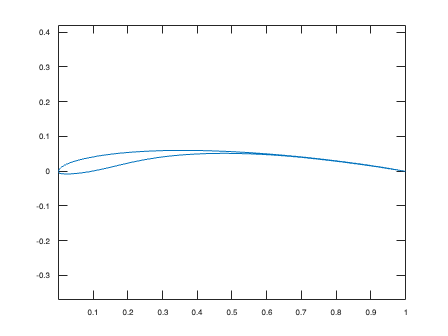

figure(1)
plot(p.xb, p.yb)
axis equal

Visualize results: 

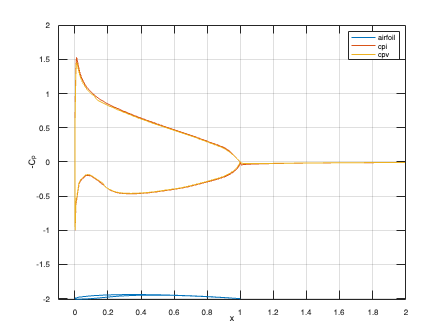

figure(2)
plot(p.xb,p.yb-2,p.x,-p.cpi,p.x,-p.cpv)
    xlabel('x')
    ylabel('-C_p')
    legend('airfoil','cpi','cpv')
    xlim([-0.1 2])
    grid on